# Example 12.4: An illustration in which a MOG snake cannot reach into a boundary, whereas a GVF snake can.

This example is from *Digital Image Processing Using MATLAB*, 3rd edition, by Rafael C. Gonzalez, Richard E. Woods, and Steven L. Eddins, Gatesmark Press, 2020. 

This example may use functions, images, and other data that are included with the book. For instructions on obtaining this material, or for other information about the book, visit [imageprocessingplace.com](http://imageprocessingplace.com/DIPUM-3E/dipum3e_main_page.htm).

Copyright 2020-2021, Gatesmark Press

Figure 12.7(a) is a classic image used to illustrate the advantages that can result from using GVF instead of MOG vector fields. The object’s boundary is smooth, but has a deep, narrow concavity of the type that often proves difficult to reach by snakes based on a MOG force field. We generated the results in Fig. 12.7 using the following sequence of commands: 

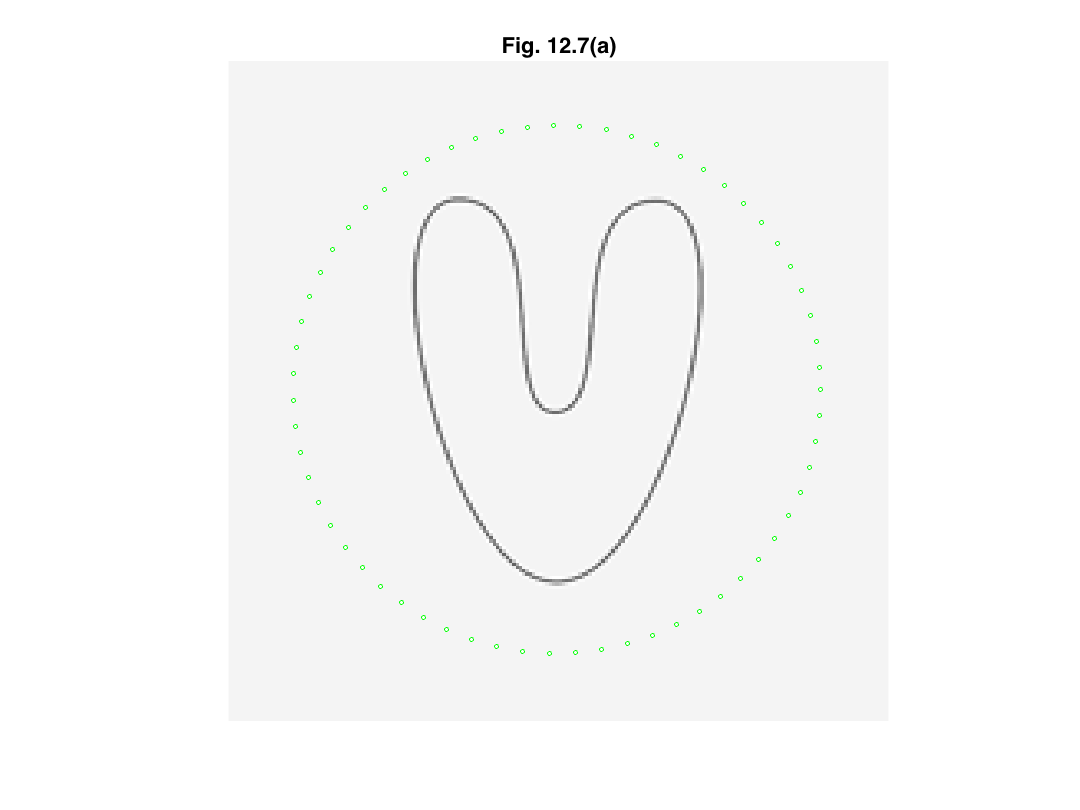

% Read image.
g = imread('U200.tif');

% Specify a circular snake.
t = 0:0.1:2*pi;
x0 = 100 + 80*cos(t)';
y0 = 100 + 80*sin(t)';

% Close the snake.

x0(end + 1) = x0(1);
y0(end + 1) = y0(1);

% Display the snake superimposed on the image.
figure, imshow(g)
hold on
curveDisplay(y0,x0,'go','MarkerFaceColor','w','MarkerSize',2)
title('Fig. 12.7(a)')
hold off

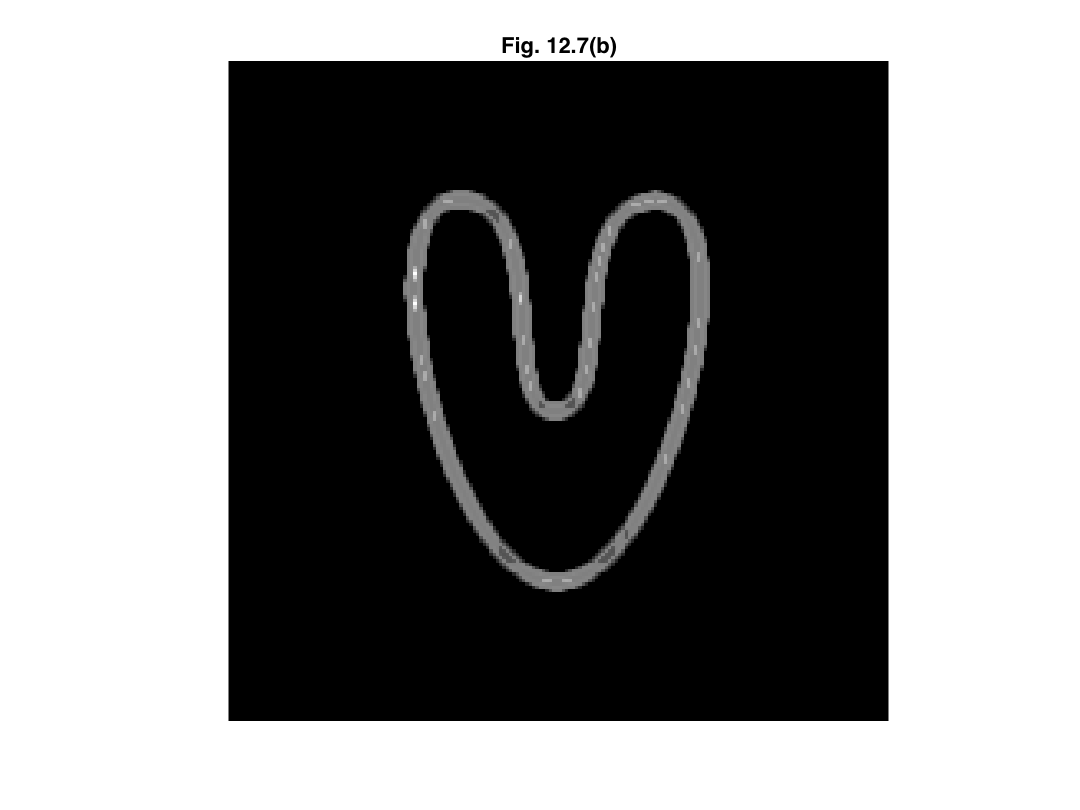

% Edge map.
emap = snakeMap(g, 0.001,3,1,'both');

% Scale to range [0,1].
emap = im2double(intensityScaling(emap));
figure, imshow(emap,[]), title('Fig. 12.7(b)')

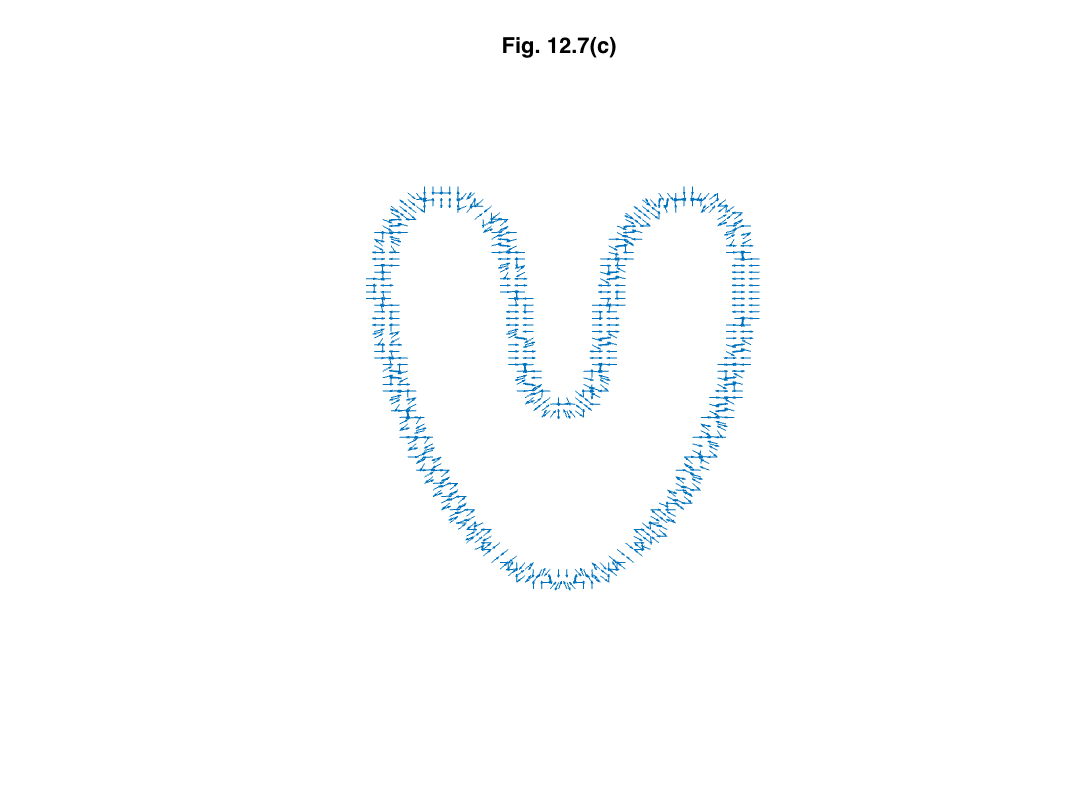


% Snake force.
[FMx,FMy] = snakeForce(emap,'MOG');
mag = hypot(FMx,FMy);
small = 1e-10;

% Normalize the force.
FMx = FMx./(mag + small);
FMy = FMy./(mag + small);
			
% Plot the normalized force field (see Example 12.2 regarding function quiver).
figure, quiver(flipud(FMy(1:2:end,1:2:end)),flipud(-FMx(1:2:end,1:2:end)))
title('Fig. 12.7(c)')
axis off

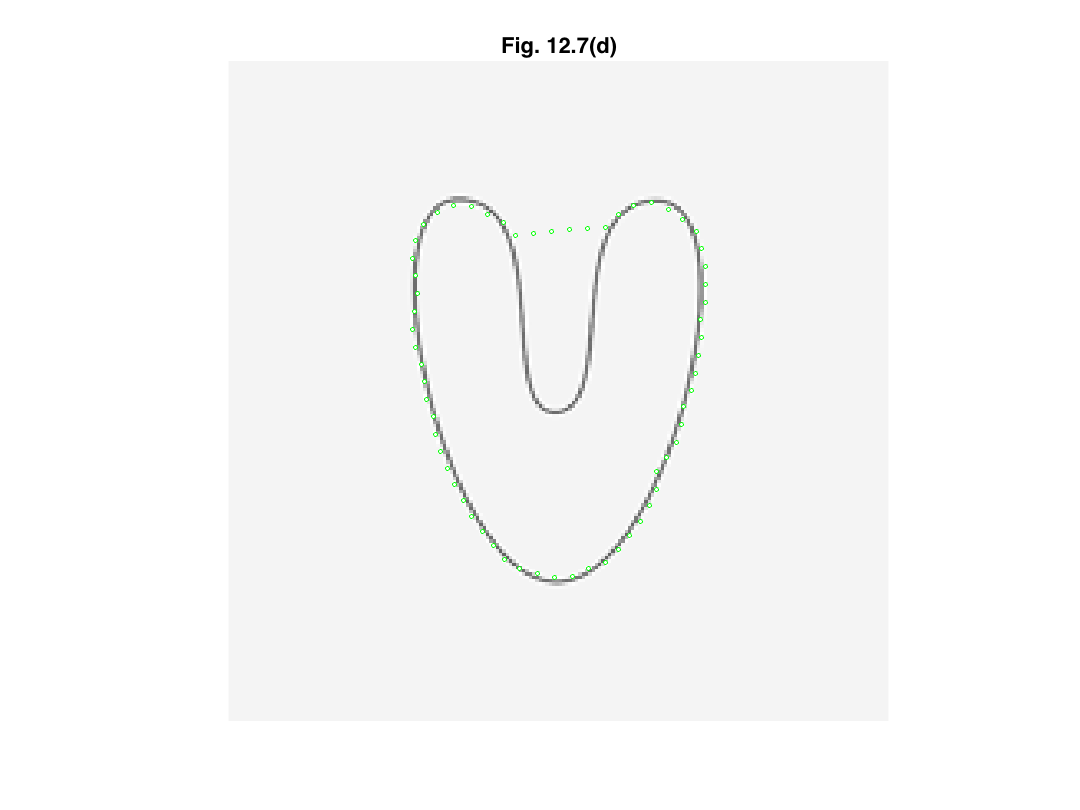

				
x = x0;
y = y0;
% 1000 iterations. More iterations would yield the same result.
for j = 1:1000
    [x,y] = snakeIterate(0.06, 0, 1, x, y, 1, FMx, FMy);
    [x,y] = snakeRespace(x,y);
end 
					
% Respace the snake points one last time.
[x,y] = snakeRespace(x,y);

% Display the snake superimposed on the image.
figure, imshow(g)
hold on
curveDisplay(x,y,'go','MarkerFaceColor','w','MarkerSize',2) 
title('Fig. 12.7(d)')
axis off
hold off

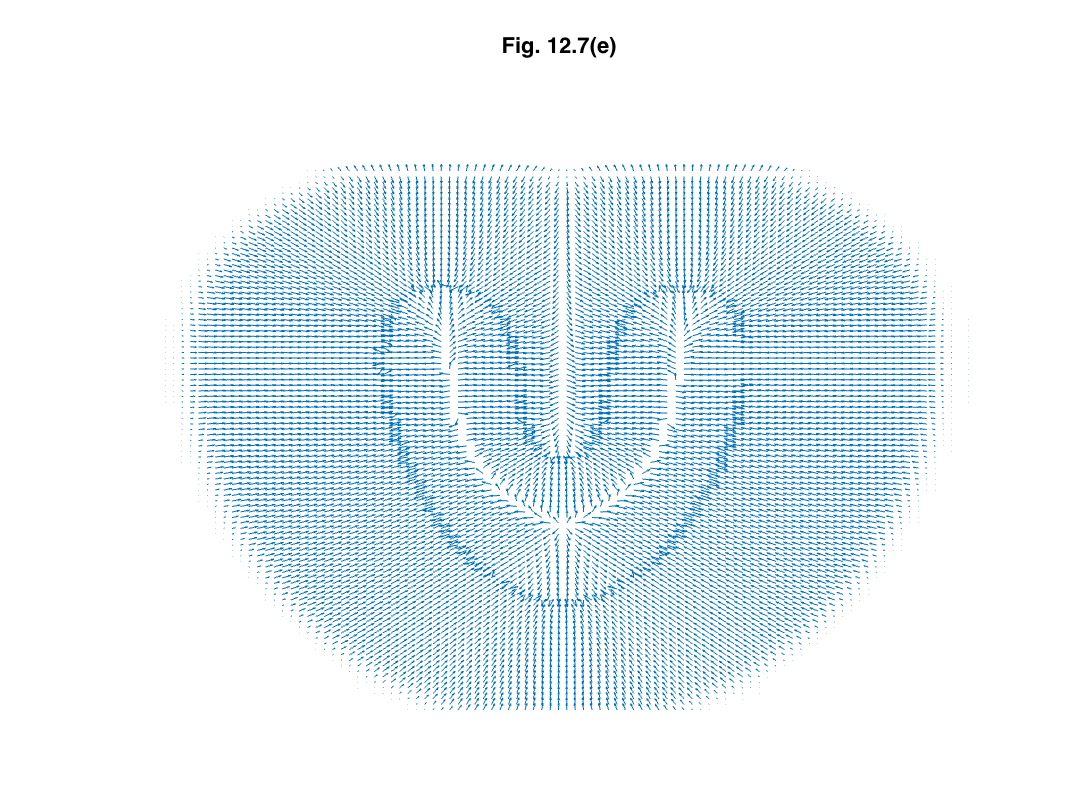


% Now do with a GVF force.

% GVF snake force using the same edge map as before.
[FVx,FVy] = snakeForce(emap,'gvf',0.25,100);
small = 1e-10;

% Normalize the force.
mag = sqrt(FVx.^2 + FVy.^2);
FVx = FVx./(mag + small);
FVy = FVy./(mag + small);

% Plot the normalized force field.
figure, quiver(flipud(FVy(1:2:end,1:2:end)),flipud(-FVx(1:2:end,1:2:end)))
title('Fig. 12.7(e)')
axis off

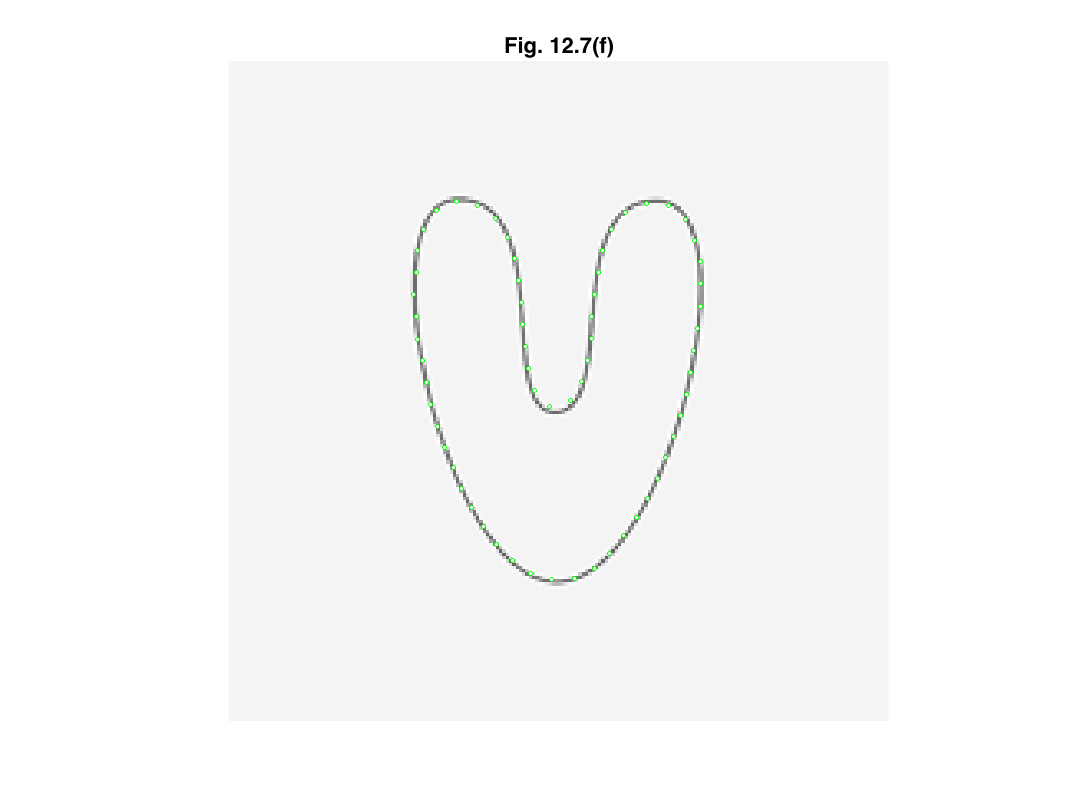


x = x0;
y = y0;
% 400 iterations.
for j = 1:400
    [x,y] = snakeIterate(0.06, 0, 1, x, y, 1, FVx, FVy);
    [x,y] = snakeRespace(x,y);
end 
					
% Respace the snake points one last time.
[x,y] = snakeRespace(x,y);

% Display the resulting GVF snake superimposed on the image.
figure, imshow(g)
hold on
curveDisplay(x,y,'go','MarkerFaceColor','w','MarkerSize',2)
title('Fig. 12.7(f)')
hold off

Figure 12.7(b) is the edge map obtained using the parameters shown in the call to function `snakeMap` (the kernel is so small with respect to the value of `s` that its shape is more like a box kernel). Figure 12.7(c) is the normalized MOG force field superimposed on the edge map. As in Fig. 12.6(b), the force is localized near the region boundary. Figure 12.7(d) shows the snake after 1,000 iterations using the parameters in the figure caption. No further changes resulted with additional iterations, so the snake shown is the best possible solution for the force field and parameters specified. Although the snake was able to shrink to the outer region boundary, it clearly missed the most important feature of the object. 

Figure 12.7(e) is the GVF force field generated using the parameters listed in the call to function `snakeForce`. Figure 12.7(f) shows the resulting GVF snake after 400 iterations. This result shows that the snake snapped to the entire contour, including the deep concavity that the MOG snake could not reach. Because of its breadth and strength a GVF force field again proved superior. As in the previous example, using a GVF force also reduced the number of iterations. Unlike that example, however, a GVF force in this case was essential for achieving a correct segmentation.